## Project 2

**Name: Shrey Patel**

**Loading the dataset of handwritten digits collected by USPS**

load usps_all.mat

% data. Dimension = 256x1100x10
% 256 pixels, 1100 instances of 10 digits(1,2,...0)

**I. Performing PCA**

% Creating digits matrix (1100x256x10) where each row correspond to an
%   observation/example (1100) and each column corresponds to a
%   variable/feature (256)
[var,obs,tot] = size(data); % [256,1100,10]
digits = zeros(obs,var,tot); % [1100,256,10]
for i = 1:tot
    digits(:,:,i) = data(:,:,i)';
end

% PCA on the whole dataset
% The principal components coefficients are stored in 'coeff' matrix,
% where these 'obs' (or 256) principal components form the orthogonal basis
% for the 256 dimensional space, and are ordered from hightest component
% variance to least. Meaning, 1st is the most imp component and the 256th
% is the least.
coeff = zeros(var,var,tot);
score = zeros(obs,var,tot);
latent = zeros(var,1,tot);
mu = zeros(1,var,tot);
for i = 1:tot
   [coeff(:,:,i),score(:,:,i),latent(:,:,i),~,~,mu(:,:,i)] ...
                = pca(digits(:,:,i)); 
end
warning('off');

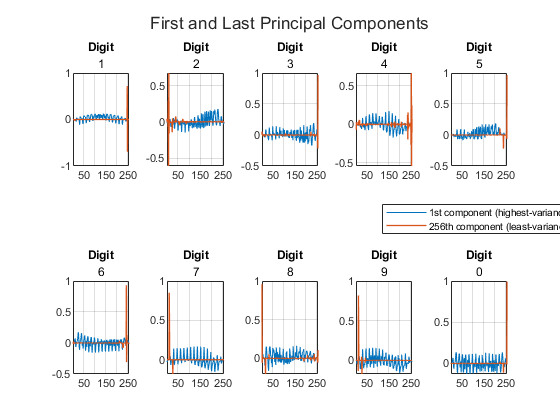

% Plotting the first and last principal components as functions on x=1:256
t = tiledlayout(2,5);
nexttile;
title(t, 'First and Last Principal Components')
for i = 1:tot
    p = plot(1:256,coeff(:,[1,256],i));
    grid;
    p(2).LineWidth = 1;
    if i==tot
        title("Digit",0)
    else
        title("Digit",i)
    end
    xlim([1 256])
    if i~=tot
        nexttile;
    end
end
legend({'1st component (highest-variance)','256th component (least-variance)'},...
            'Location',"northoutside");

**II. Representing the data in the new basis of principal components we obtained in the last section.**

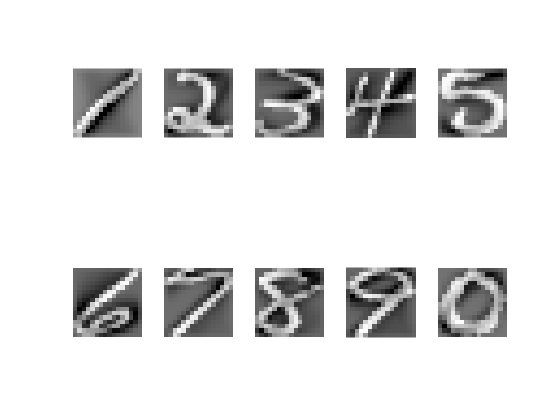

X_rep = zeros(obs,var,tot);
for i = 1:tot
    % centered data
   X_rep(:,:,i) = score(:,:,i)*coeff(:,:,i)';
end
% reshaping each representation as an image
% (the first example of each digit)
for i = 1:tot
    subplot(2,5,i)
    imshow(reshape(score(1,:,i),[16 16]),[])
end

% reshaping each representation as an image
% (the first example of each digit)
for i = 1:tot
    subplot(2,5,i)
    imshow(reshape(X_rep(1,:,i),[16 16]),[])
end

**III. Using the PCA represented data, we perform kNN classification using the optimal parameters from last project**

- The optimal training-testing size obtained from the last project was 1050-50, where first 1050 examples of each digit go into training and the rest 50 go into test.

- Metric: Euclidean

- k = 20 Nearest Neighbors

**1.** Splitting data

% Data set X_rep [obs,var,tot]:[1100,256,10]
split = 1050;
% First 1050 in training set & Rest 50 in testing set
x_train = zeros(var,split,tot); % [256x1050x10]
x_test = zeros(var,obs-split,tot); % [256x50x10]
for i = 1:tot
    x_train(:,:,i) = X_rep(1:split,:,i)';
    x_test(:,:,i) = X_rep(split+1:end,:,i)';
end
% reshaping from [256x1050x10] and [256x50x10] to [10500x256] and [500x256]
x_train = x_train(:,:)';
x_test = x_test(:,:)';
% Each row in training set is an observation/example and 
%   each row in test set is a query point that 
%   needs to classified based on k nearest neighbors from training set

% creating training and testing labels
for i = 1:1050:10500
    train_label(i:i+1049,:) = ceil(i/1050);
end
for i = 1:50:500
    test_label(i:i+49,:) = ceil(i/50);
end

**2. **Performing validation to obtain an optimal 'k' for our dataset. First 900 in train and the next 150 to validate.

% splitting training-set(x_train) into validation-set(x_valid) and 
% a subset of training-set(x_sub_train)
x_sub_train = zeros(var,900,tot); % [256x900x10]
x_valid = zeros(var,150,tot); % [256x150x10]
for i = 1:tot
    x_sub_train(:,:,i) = X_rep(1:900,:,i)';
    x_valid(:,:,i) = X_rep(901:1050,:,i)';
end
% reshaping
x_sub_train = x_sub_train(:,:)';
x_valid = x_valid(:,:)';
% creating training and validation labels
for i = 1:900:9000
    subtr_label(i:i+899,:) = ceil(i/900);
end
for i = 1:150:1500
    val_label(i:i+149,:) = ceil(i/150);
end
accuracy = zeros(20,1);
for k = 1:20
    idx = knnsearch(double(x_sub_train),double(x_valid),'K',k,...
        'Distance',"euclidean");
    idc = ceil(idx/900);
    pred_labels = mode(idc,2);
    accuracy(k,:) = (1-(length(find(pred_labels~=val_label))/1500))*100;
end
[val,pos] = min(abs(accuracy-mean(accuracy)))

val = 0.3833

pos = 10

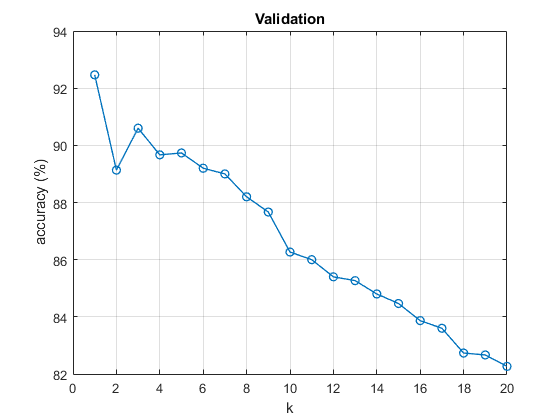

figure;
plot(accuracy,'-o','MarkerIndices',1:1:20,'DisplayName','Accuracy','LineWidth',1);
title('Validation')
xlabel('k')
ylabel('accuracy (%)')
grid on;

**3. **kNN using the optimal value of 'k' and k=20

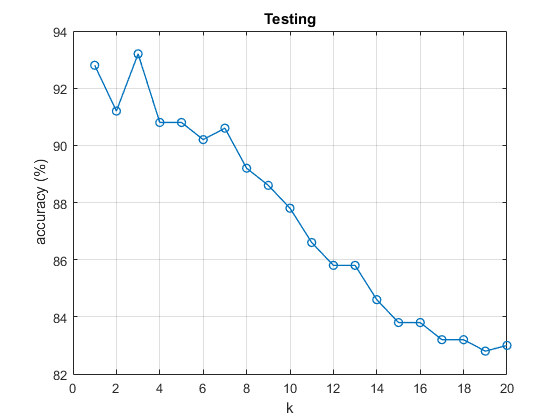

% kNN - testing
%------------------------------------------------------------------------------
% for all k from 1 to 20
accuracy = zeros(20,1);
for k = 1:20
    idx = knnsearch(double(x_train),double(x_test),'K',k,'Distance',"euclidean");
    idc = ceil(idx/1050);
    pred_labels = mode(idc,2);
    accuracy(k,:) = (1-(length(find(pred_labels~=test_label))/500))*100;
end

plot(accuracy,'-o','MarkerIndices',1:1:20,'DisplayName','Accuracy','LineWidth',1);
title('Testing')
xlabel('k')
ylabel('accuracy (%)')
grid on;

%------------------------------------------------------------------------------
% when k is optimal
k_optimal = pos;
idx = knnsearch(double(x_train),double(x_test),'K',k_optimal,'Distance',"euclidean");
idc = ceil(idx/1050);
pred_labels = mode(idc,2);
acc = (1-(length(find(pred_labels~=test_label))/500))*100;
fprintf("Global accuracy score with optimal k = %d is %f \n",k_optimal,acc);

Global accuracy score with optimal k = 10 is 87.800000 


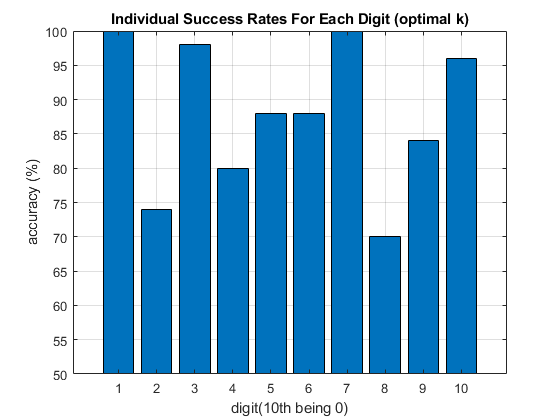


success_rate = zeros(10,1);
for i = 1:50:500
    success_rate(ceil(i/50))=(1-(length(find(pred_labels(i:i+49)~=test_label(i:i+49)))/50))...
                                *100;
end

bar(success_rate)
title('Individual Success Rates For Each Digit (optimal k)')
ylim([50,100])
grid;
xlabel('digit(10th being 0)')
ylabel('accuracy (%)')


%------------------------------------------------------------------------------
% when k=20

idx = knnsearch(double(x_train),double(x_test),'K',20,'Distance',"euclidean");
idc = ceil(idx/1050);
pred_labels = mode(idc,2);
acc = (1-(length(find(pred_labels~=test_label))/500))*100;
fprintf("Global accuracy score with k = %d is %f \n",20,acc);

Global accuracy score with k = 20 is 83.000000 


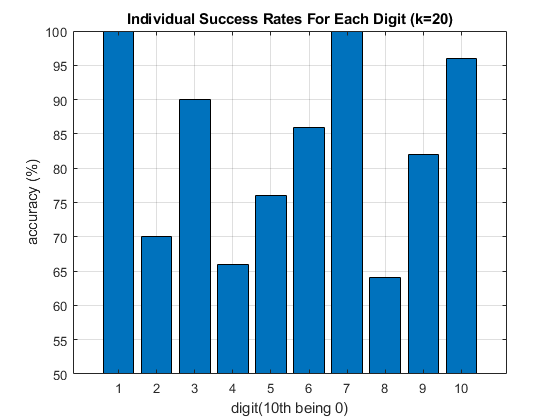


success_rate = zeros(10,1);
for i = 1:50:500
    success_rate(ceil(i/50))=(1-(length(find(pred_labels(i:i+49)~=test_label(i:i+49)))/50))...
                                *100;
end

bar(success_rate)
title('Individual Success Rates For Each Digit (k=20)')
ylim([50,100])
grid;
xlabel('digit(10th being 0)')
ylabel('accuracy (%)')

**III. kNN without PCA**

training_set = data(:,1:1050,:);
testing_set = data(:,1051:end,:);
train = training_set(:,:)';
test = testing_set(:,:)';


idx = knnsearch(double(train),double(test),'K',20,'Distance',"euclidean");
idc = ceil(idx/1050);
pred_labels = mode(idc,2);
acc = (1-(length(find(pred_labels~=test_label))/500))*100;
fprintf("Global accuracy score without PCA for k = %d is %f \n",20,acc);

Global accuracy score without PCA for k = 20 is 90.800000 


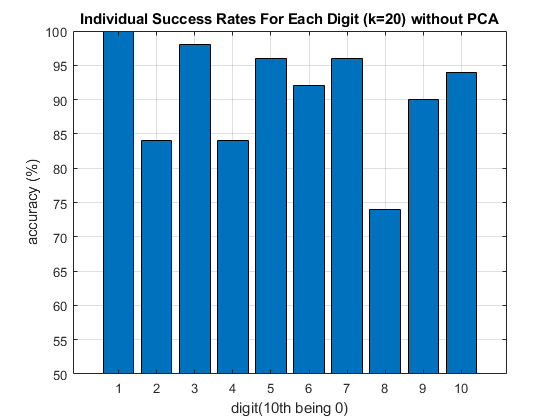


success_rate = zeros(10,1);
for i = 1:50:500
    success_rate(ceil(i/50))=(1-(length(find(pred_labels(i:i+49)~=test_label(i:i+49)))/50))...
                                *100;
end

bar(success_rate)
title('Individual Success Rates For Each Digit (k=20) {without PCA}')
ylim([50,100])
grid;
xlabel('digit(10th being 0)')
ylabel('accuracy (%)')